# Basic ISETBio and Image Reconstruction Calculation

## Generate a retina with human optics and cone mosaic

% load the display setup
display = load('CRT12BitDisplay.mat');

% 1.0 deg mosaic with a pupil size of 2.5 mm
retina = ConeResponse('eccBasedConeDensity', true, 'eccBasedConeQuantal', true, ...
    'fovealDegree', 1.0, 'display', display.CRT12BitDisplay, 'pupilSize', 2.5);

Create cone moasic object: 
Will do 3 passes
[PASS:  0/ 0]. Adjusting cones between 0.00 225.00 using posDiffTolerange: 0.200000

Hex grid adjustment: on iteration 0 ... 
Hex grid adjustment: on iteration 1 ... 
Hex grid adjustment: on iteration 2 ... 
Hex grid adjustment: on iteration 3 ... 
Hex grid adjustment: on iteration 4 ... 
Hex grid adjustment: on iteration 5 ... 
Hex grid adjustment: on iteration 6 ... 
Hex grid adjustment: on iteration 7 ... 
Hex grid adjustment: on iteration 8 ... 
Hex grid adjustment: on iteration 9 ... 
Hex grid adjustment: on iteration 10 ... 
Hex grid smoothing finished.
Did not converge, but exceeded max number of iterations (10).
Max(movement) in last iteration: 0.714435, Tolerange: 0.001000
Number of Delaunay triangulations: 11
[PASS:  1/ 3]. Adjusting cones between 225.00 229.64 using posDiffTolerange: 0.200000

Hex grid adjustment: on iteration 0 ... 
Hex grid adjustment: on iteration 1 ... 
Hex grid adjustment: on iteration 2 ... 
Hex grid adjustm

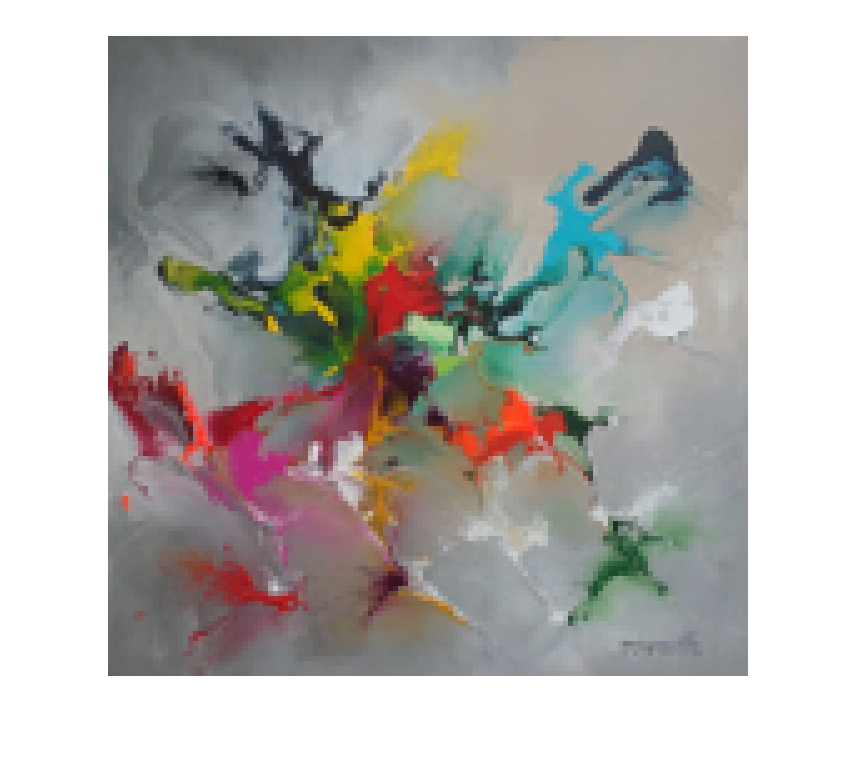

% load an example image
imageSize = [128, 128, 3];
image = im2double(imread('artwork.png'));
image = imresize(image, imageSize(1) / size(image, 1));

% normalize to insure pixels are in the range of [0, 1]
image = (image - min(image(:)));
image = image ./ max(image(:));

assert(min(image(:)) >= 0);
assert(max(image(:)) <= 1);

figure();
imshow(image, 'InitialMagnification', 500);

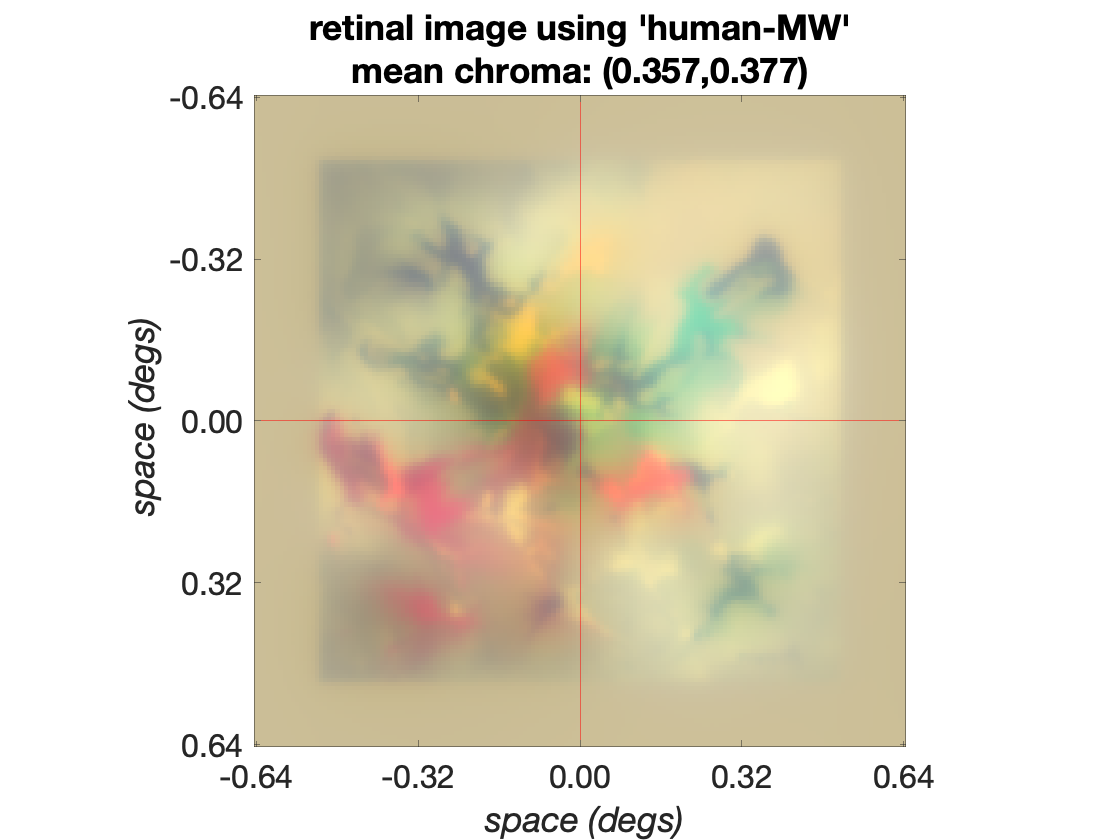

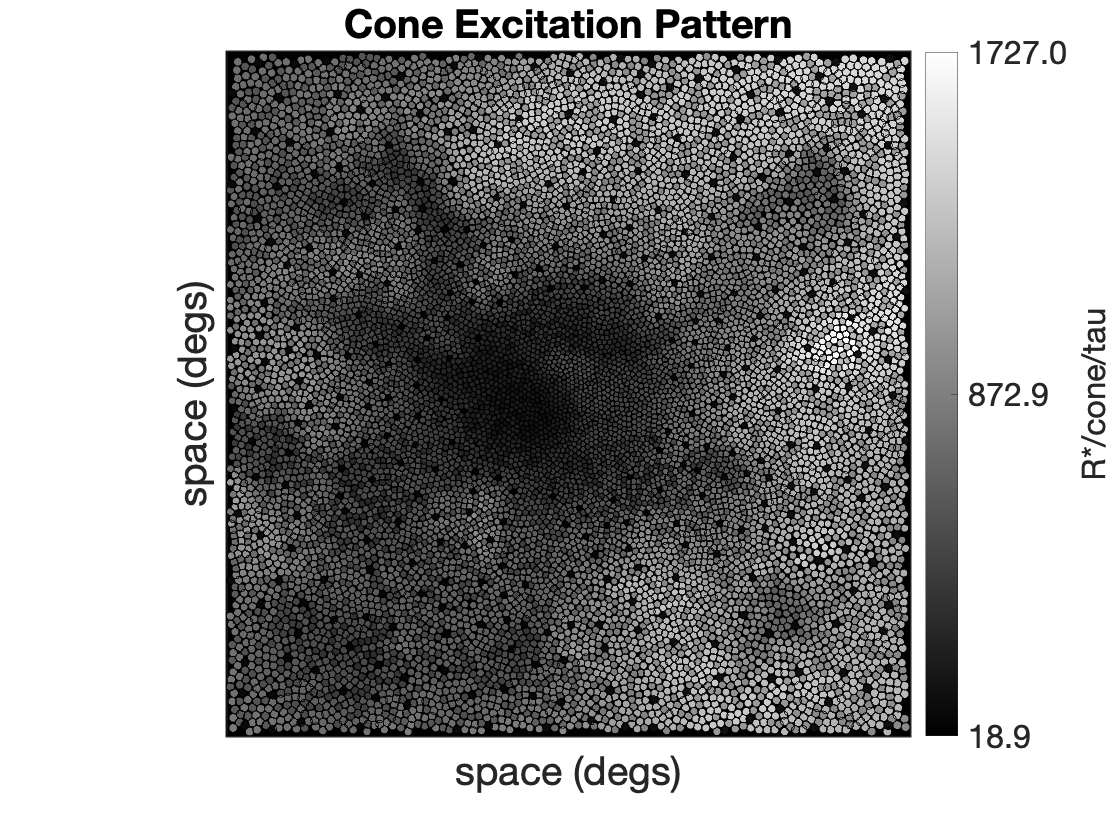

% demo of compute cone responses
[excitation, ~, linearImage, allCone] = retina.compute(image);

retina.visualizeOI();
retina.visualizeExcitation();

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


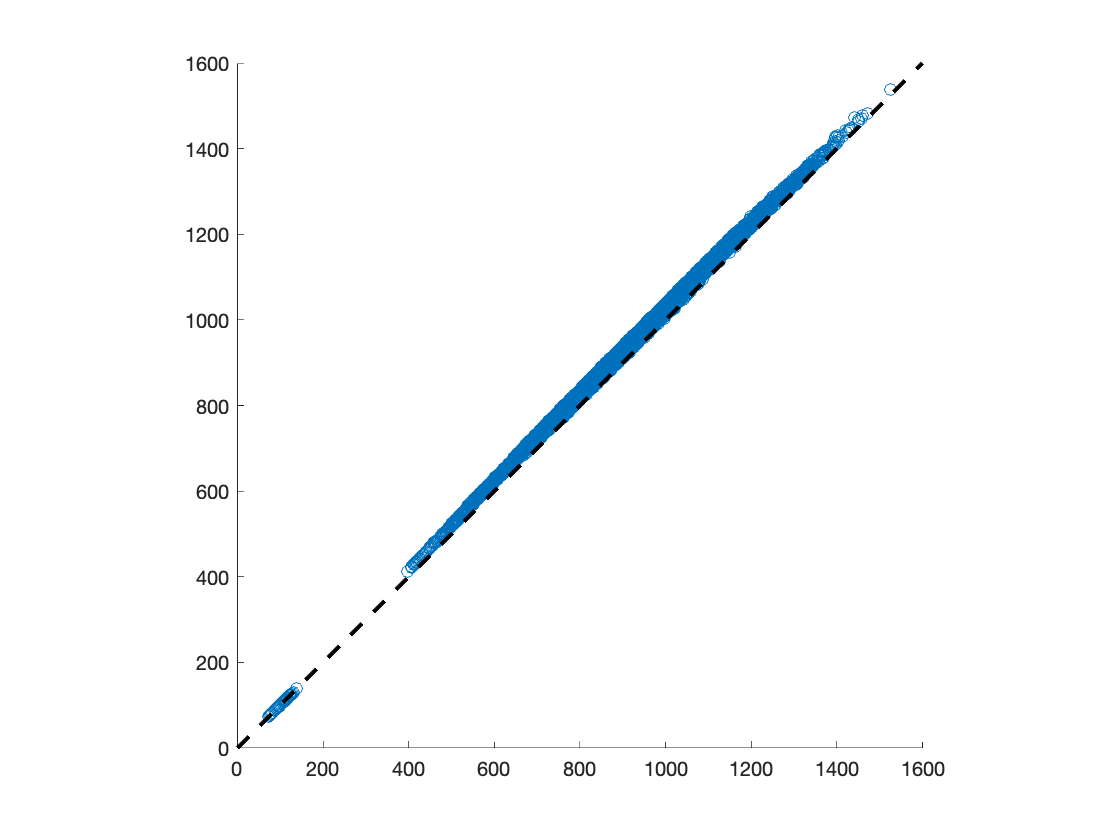

% compute render matrix to represent the
% ISETBio calculation as a linear transformation

% note that this process is computation-intense
% reduce image size and retina mosaic size (deg)
% if you would like the process to be faster
render = retina.forwardRender(imageSize);

render = double(render);

## Image reconstruction from simulated cone responses

% compute (noise-free) avearge cone response
response = render * linearImage(:);

% cone response with Poisson noise
% response = poissrnd(response);

% construct image estimator
prior = load('sparsePrior.mat');
estimator = PoissonSparseEstimator(render, inv(prior.regBasis), prior.mu', 1e-3, 4, imageSize);

% estimate images
% computation intense if large image size and cone mosaic is used
reconImage = estimator.estimate(response, 1.0e3, rand([prod(imageSize), 1]), true, 1.0, 'final');


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 1.000000e+03.



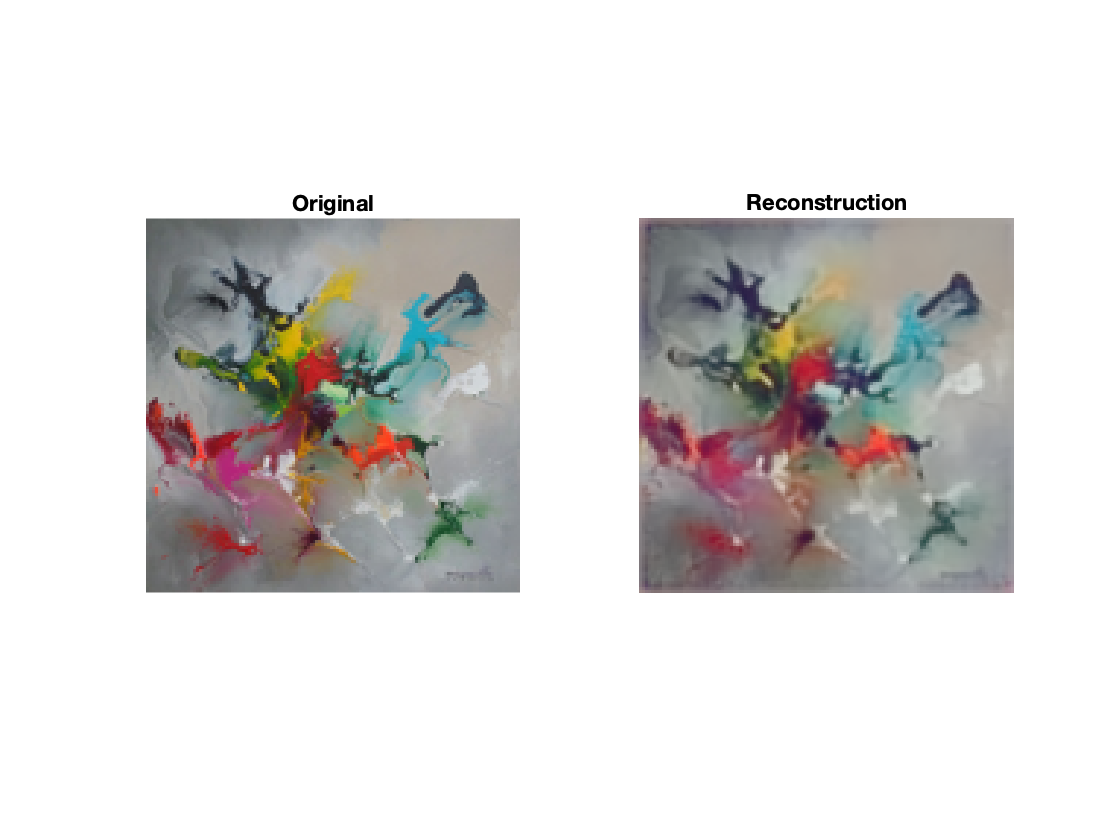

% compare the original and reconstructed images
figure();
subplot(1, 2, 1);
imshow(image, 'InitialMagnification', 500);
title('Original')

% reconstructed image is in linear pixel space
% convert it back to RGB space
recon = gammaCorrection(reconImage, display.CRT12BitDisplay);
subplot(1, 2, 2);
imshow(recon, 'InitialMagnification', 500);
title('Reconstruction')